## Report

**1a**

Loading the given data.

load('Q1_Output_2x2_Step_Response_Data.mat')

Visualizations

subplot(2,2,1)
plot(U1.time,U1.signals.values,'LineWidth',2)
hold on
plot(G11U1.time,G11U1.signals.values,'LineWidth',2)
ylabel('\textbf{$G_{11}U_1$}','FontSize',11,'interpreter','latex');
xlabel('Time','FontSize',11,'FontWeight','bold');
title('\textbf{Step Response for $G_{11}U_1$}','interpreter','latex','FontSize',11);
legend('U_1','G_{11}U_1','Location',"best")
subplot(2,2,2)
plot(U2.time,U2.signals.values,'LineWidth',2)
hold on
plot(G12U2.time,G12U2.signals.values,'LineWidth',2)
ylabel('\textbf{$G_{12}U_2$}','FontSize',11,'interpreter','latex');
xlabel('Time','FontSize',11,'FontWeight','bold');
title('\textbf{Step Response for $G_{12}U_2$}','interpreter','latex','FontSize',11);
legend('U_2','G_{12}U_2','Location',"best")

subplot(2,2,3)
plot(U1.time,U1.signals.values,'LineWidth',2)
hold on
plot(G21U1.time,G21U1.signals.values,'LineWidth',2)
ylabel('\textbf{$G_{21}U_1$}','FontSize',11,'interpreter','latex');
xlabel('Time','FontSize',11,'FontWeight','bold');
title('\textbf{Step Response for $G_{21}U_1$}','interpreter','latex','FontSize',11);
legend('U_1','G_{21}U_1','Location',"best")

subplot(2,2,4)
plot(U2.time,U2.signals.values,'LineWidth',2)
hold on
plot(G22U2.time,G22U2.signals.values,'LineWidth',2)
ylabel('\textbf{$G_{22}U_2$}','FontSize',11,'interpreter','latex');
xlabel('Time','FontSize',11,'FontWeight','bold');
title('\textbf{Step Response for $G_{22}U_2$}','interpreter','latex','FontSize',11);
legend('U_2','G_{22}U_2','Location',"best")

Estimating transfer functions G11, G12, G21 and G22 using tfest method.

G11

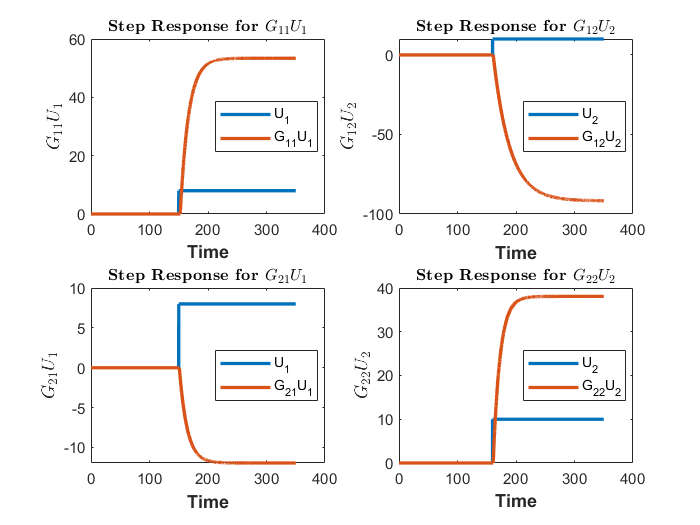

G11U1_iddata = iddata(G11U1.signals.values,U1.signals.values,0.1);
%From the step Response plot we can identify the delay to be 2.5s
G11 = tfest(G11U1_iddata,1,0,2.5);

G11

G11 =
 
  From input "u1" to output "y1":
                   0.469
  exp(-2.5*s) * -----------
                s + 0.07025
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using TFEST on time domain data "G11U1_iddata".
Fit to estimation data: 99.81%                           
FPE: 0.002442, MSE: 0.002438                             


G12

G12U2_iddata = iddata(G12U2.signals.values,U2.signals.values,0.1);
%From the step Response plot we can identify the delay to be 1.1s
G12 = tfest(G12U2_iddata,1,0,1.1);
G12

G12 =
 
  From input "u1" to output "y1":
                  -0.3245
  exp(-1.1*s) * -----------
                s + 0.03536
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using TFEST on time domain data "G12U2_iddata".
Fit to estimation data: 99.89%                           
FPE: 0.001959, MSE: 0.001956                             


G21

G21U1_iddata = iddata(G21U1.signals.values,U1.signals.values,0.1);
%From the step Response plot we can identify the delay to be 1.1s
G21 = tfest(G21U1_iddata,1,0,1.1);
G21

G21 =
 
  From input "u1" to output "y1":
                  -0.1132
  exp(-1.1*s) * -----------
                s + 0.07582
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using TFEST on time domain data "G21U1_iddata".
Fit to estimation data: 99.85%                           
FPE: 7.535e-05, MSE: 7.522e-05                           


G22

G22U2_iddata = iddata(G22U2.signals.values,U2.signals.values,0.1);
%From the step Response plot we can identify the delay to be 1.1s
G22 = tfest(G22U2_iddata,1,0,1.1);
G22

G22 =
 
  From input "u1" to output "y1":
                  0.3288
  exp(-1.1*s) * -----------
                s + 0.08636
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using TFEST on time domain data "G22U2_iddata".
Fit to estimation data: 99.68%                           
FPE: 0.003464, MSE: 0.003458                             
